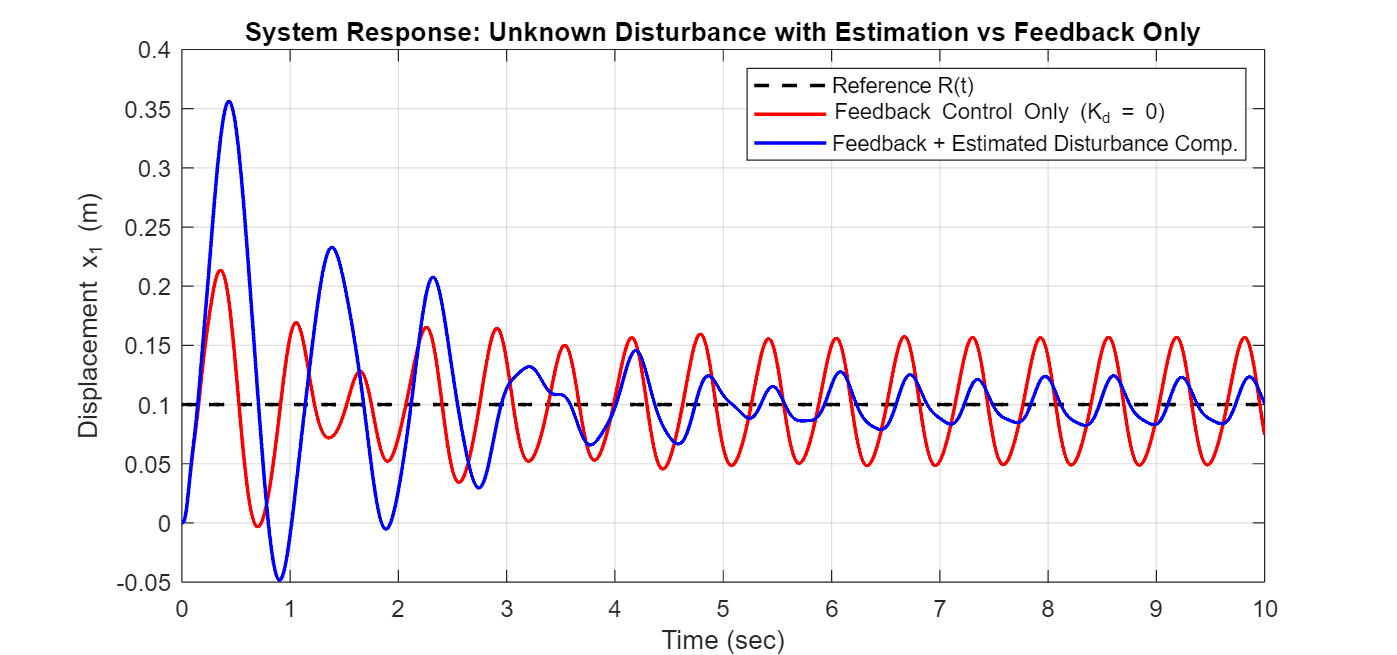

clc; clear; close all;

numG = [1 0 3000]; 
denG = [300 7000 1005000 3000000 45000000]; 
G = tf(numG, denG);

numH = 3000000 * [1 15]; 
denH = denG;
H = tf(numH, denH);

Kp = 1601; 
Ki = 20950;
C = pid(Kp, Ki); 

G0 = dcgain(G); 
H0 = dcgain(H); 
Kd = -H0 / G0; 
tau = 0.01; 
F = tf(1, [tau 1]); 


term = 1 + F * G * (1/G0); 
C_eq1 = C / term;
C_eq2 = (C - F * (1/G0)) / term;


T_ref_est = minreal((G * C_eq1) / (1 + G * C_eq2));
T_dist_est = minreal(H / (1 + G * C_eq2));

T_ref_base = feedback(C * G, 1);
T_dist_base = H / (1 + C * G);

t = 0:0.001:10;
R = 0.1 * ones(size(t)); 
Yr = 0.1 + 0.05*sin(10*t) + 0.02*cos(20*t);

y_base = lsim(T_ref_base, R, t) + lsim(T_dist_base, Yr, t);

y_est_comp = lsim(T_ref_est, R, t) + lsim(T_dist_est, Yr, t);

figure('Name', 'Part 4: Estimator Performance', 'Units', 'normalized', 'Position', [0.2 0.2 0.6 0.5], 'Color', 'w');
plot(t, R, 'k--', 'LineWidth', 1.5); hold on;
plot(t, y_base, 'r', 'LineWidth', 1.5);
plot(t, y_est_comp, 'b', 'LineWidth', 1.5);
grid on;
title('System Response: Unknown Disturbance with Estimation vs Feedback Only');
xlabel('Time (sec)'); ylabel('Displacement x_1 (m)');
legend('Reference R(t)', 'Feedback Control Only (K_d = 0)', 'Feedback + Estimated Disturbance Comp.');